clc;
close all;
clear all;

## Consensus

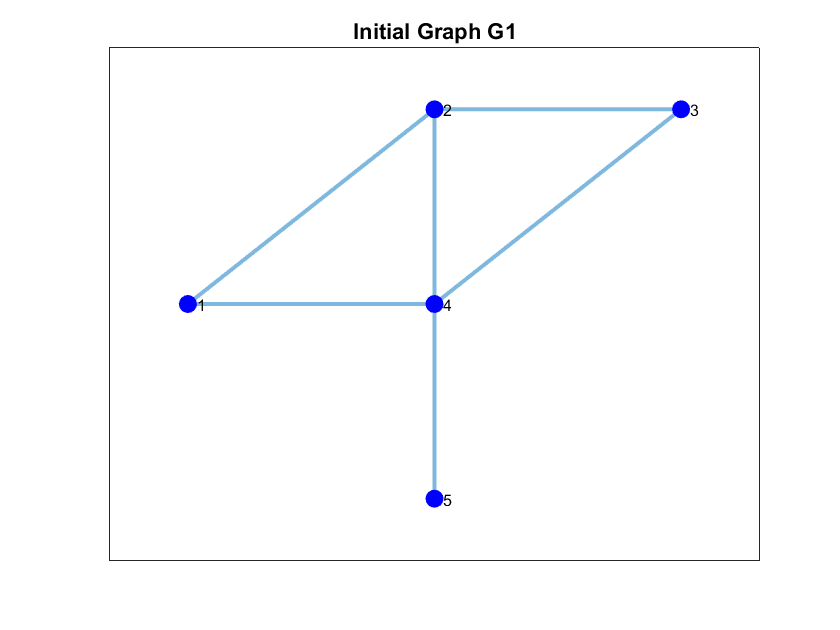

% GRAPH/DIGRAPH #1/2
Gx=[1 2 3 2 2];
Gy=[1 2 2 1 0];


% GRAPH #1
edgesG1 = [1 2; 1 4; 2 3; 2 4; 3 4; 4 5];
figure; G1 = graph(edgesG1(:,1),edgesG1(:,2));
plot(G1,'XData',Gx,'YData',Gy,'MarkerSize',8,'NodeColor','b', 'LineWidth',2);
xticks([]); yticks([]); title('Initial Graph G1')

A=[0 1 0 1 0; 1 0 1 1 0; 0 1 0 1 0; 1 1 1 0 1; 0 0 0 1 0];
D=diag([2 3 2 4 1]);
L=D-A;

% CASE 1 - limit case
eps = 0.25;
P = eye(5)-eps*L

P =     0.5000    0.2500         0    0.2500         0
    0.2500    0.2500    0.2500    0.2500         0
         0    0.2500    0.5000    0.2500         0
    0.2500    0.2500    0.2500         0    0.2500
         0         0         0    0.2500    0.7500


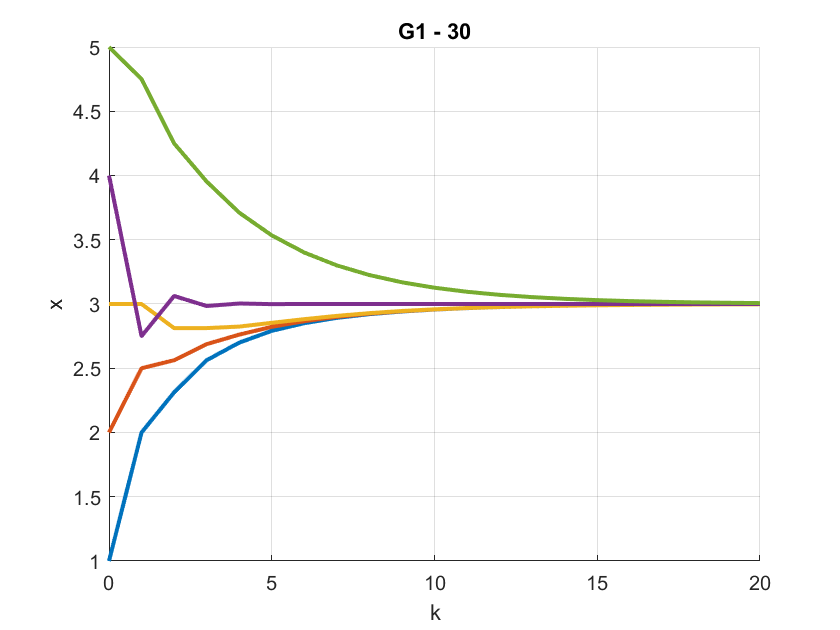

figure
x0=[1,2,3,4,5]';
%
xall=[]; kall=[];
for k=0:20; xall=[xall, P^k*x0]; kall=[kall, k]; end
xlabel('k'); ylabel('x'); hold on; grid on
plot(kall,xall,'LineWidth',2); title('G1 - 30')

Position

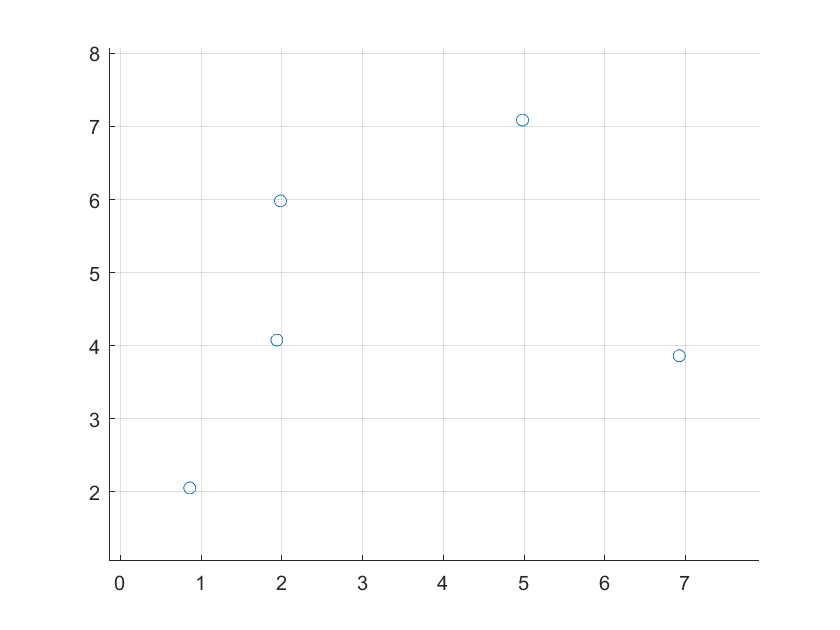

x0=randi(7,[2,5])';
e=0.1*randn([2,5])';
x0=x0+e;
%initial conditions
figure;
hold on;
grid on;
plot(x0(:,1),x0(:,2),"o");
xlim([min(x0(:,1))-1,max(x0(:,1))+1]);
ylim([min(x0(:,2))-1,max(x0(:,2))+1]);

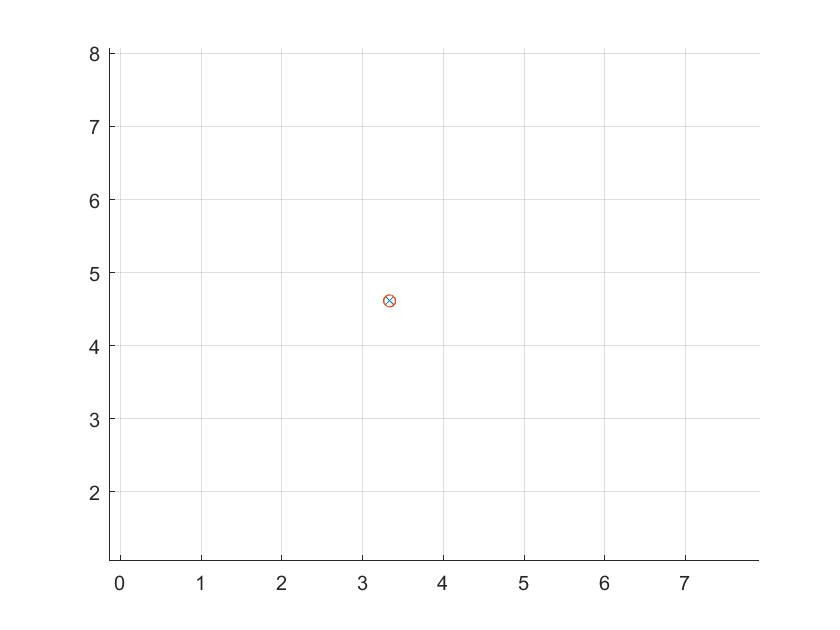

figure;
hold on;
grid on;
xc=mean(x0);
plot(xc(:,1),xc(:,2),"X");
x=zeros(size(x0));
hplot=plot(x0(:,1),x0(:,2),"o");
xlim([min(x0(:,1))-1,max(x0(:,1))+1]);
ylim([min(x0(:,2))-1,max(x0(:,2))+1]);
for k=1:20
    x(:,1)=(P^k)*x0(:,1);   
    x(:,2)=(P^k)*x0(:,2);   
    set(hplot,"XData",x(:,1),"YData",x(:,2));
    pause(1);
    drawnow;
end

xc=x(1,:); %final point


Trajectory of COM (circle)

figure;
t=0:0.01:5;
hold on;
grid on;
plot(xc(1),xc(2),"o");

m=max(abs(xc(1)-1),abs(xc(2)));
xlim([-m-1,m+1]);
ylim([-m-1,m+1]);
for k=1:length(t)
    x(:,1)=xc(1)-1+cos(2*pi*t(k));   %circle with center (xc(1)-1,xc(2)) and unitary radius (ccw motion)
    x(:,2)=xc(2)+sin(2*pi*t(k));   
    plot(x(:,1),x(:,2),".");
    drawnow;
end

Drone dynamics